%% Clear workspace
clear; close all; clc;

%% Pluto SDR IDs
plutoTX = 'usb:0';
plutoRX = 'usb:1';

%% RF parameters
fc = 2441e6;        % Center frequency (2.441 GHz)
fs = 10e6;          % Sample rate (10 MHz)
frameSize = 8192;   % Samples per frame (for smooth visualization)

%% Pluto TX Setup
txPluto = sdrtx('Pluto', 'RadioID', plutoTX, ...
    'CenterFrequency', fc, 'BasebandSampleRate', fs, 'Gain', -5);

%% Pluto RX Setup
rxPluto = sdrrx('Pluto', 'RadioID', plutoRX, ...
    'CenterFrequency', fc, 'BasebandSampleRate', fs, ...
    'GainSource', 'Manual', 'Gain', 40, ...
    'SamplesPerFrame', frameSize, 'OutputDataType', 'double');

%% Generate 20-second sine wave (adjusted to last full duration within Pluto's max sample limit)
duration = 20;                  % Total duration: 20 seconds
f_tone = 0.5 / 12;               % Frequency: Adjusted to last the full 20 seconds
numSamples = min(fs * duration, 16777216 - 1);  % Ensure it's just under the max

t = (0:numSamples-1)' / fs;
sineWave = 0.9 * exp(1j*2*pi*f_tone*t); % Explicitly complex baseband sine

% Print out size for verification
fprintf('Number of TX samples: %d (Max: 16777216)\n', numSamples);

Number of TX samples: 16777215 (Max: 16777216)


fprintf('Unrestricted num of TX samples: %d \n', fs * duration);

Unrestricted num of TX samples: 200000000 



%% Transmit sine wave
transmitRepeat(txPluto, sineWave);

## Establishing connection to hardware. This process can take several seconds.
## Waveform transmission has started successfully and will repeat indefinitely. 
## Call the release method to stop the transmission.


disp('Transmitting continuous 20-second sine wave with adjusted frequency to fit full duration.');

Transmitting continuous 20-second sine wave with adjusted frequency to fit full duration.



figure('Name', 'Pluto SDR 20-sec Live RX Signal Strength', 'NumberTitle', 'off');
hLine = plot(NaN, NaN, '-o');
xlabel('Time (s)');
ylabel('RX Signal Power (dB)');
title('Received Signal Power Over 20 Seconds');
grid on;
xlim([0 duration]);
ylim([-120 0]);

% 
% %% Setup live plotting
% numFrames = floor(numSamples/frameSize);
% rxPower = zeros(1, numFrames);
% timeVec = (0:numFrames-1)*(frameSize/fs);

%% Real-time RX loop (20-sec)
disp('Starting 20-second RX processing...');

Starting 20-second RX processing...


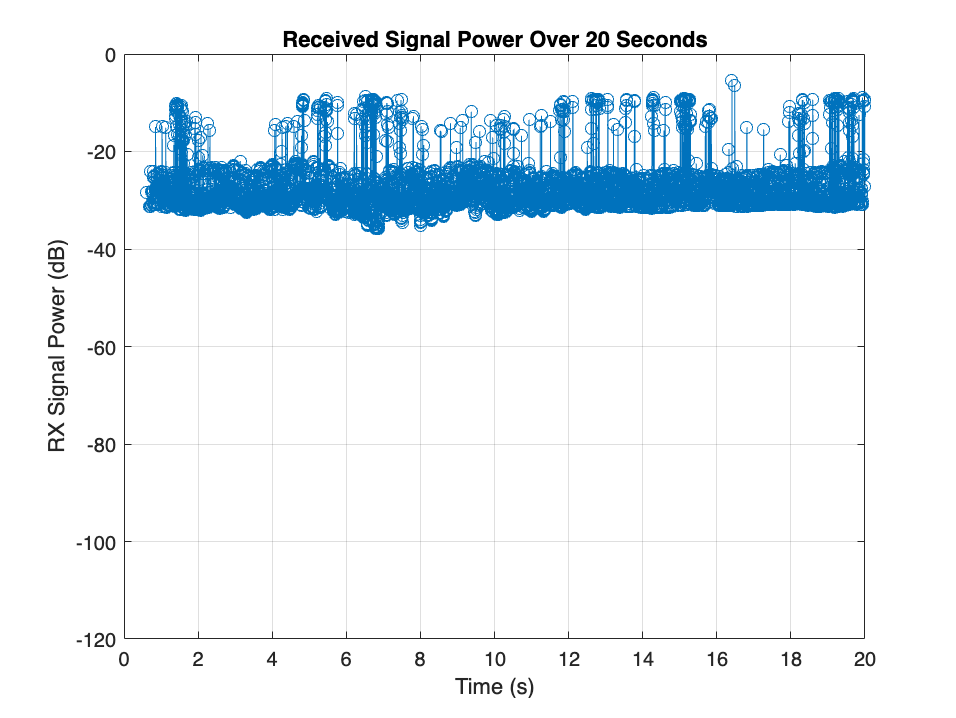

## Establishing connection to hardware. This process can take several seconds.


rxPower = []; % Store power values dynamically
timeVec = []; % Store actual timestamps
startTime = tic; % Start timing

while toc(startTime) < duration  % Run for 20 full seconds
    rxSamples = rxPluto();  % Receive frame

    % Compute power (dB)
    powerDb = 10*log10(mean(abs(rxSamples).^2));

    % Store values
    rxPower = [rxPower, powerDb]; 
    timeVec = [timeVec, toc(startTime)]; % Keep actual elapsed time

    % Update real-time plot
    set(hLine, 'XData', timeVec, 'YData', rxPower);
    drawnow limitrate;
end

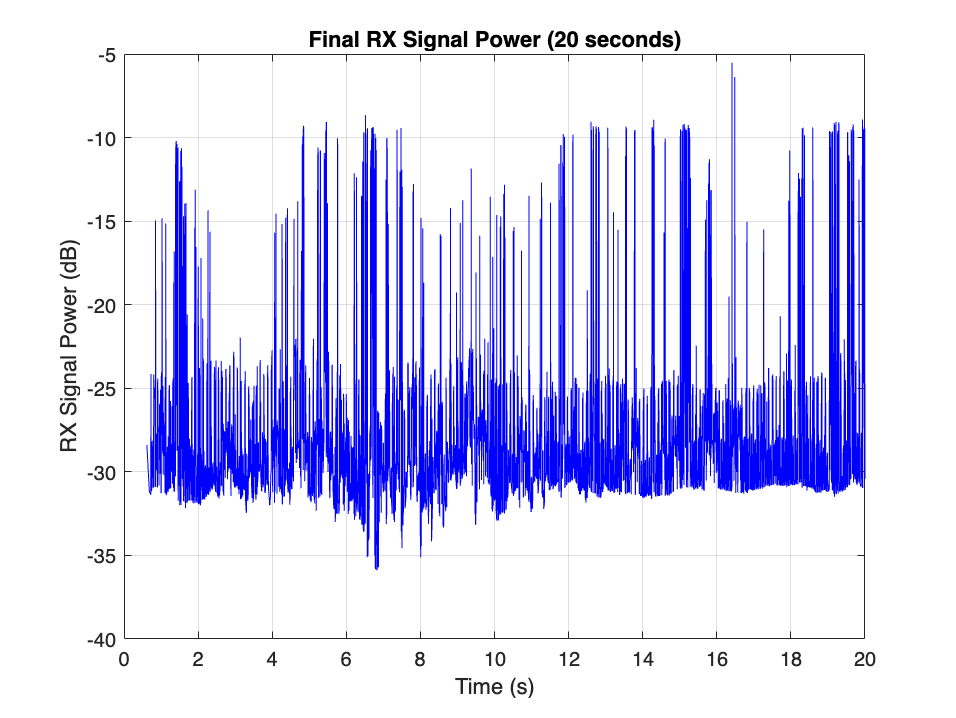


%% Final visualization (Correct full 20-second x-axis)
figure;
plot(timeVec, rxPower, '-b');
xlabel('Time (s)'); ylabel('RX Signal Power (dB)');
title('Final RX Signal Power (20 seconds)');
xlim([0 20]); % Ensure full 20 seconds
grid on;

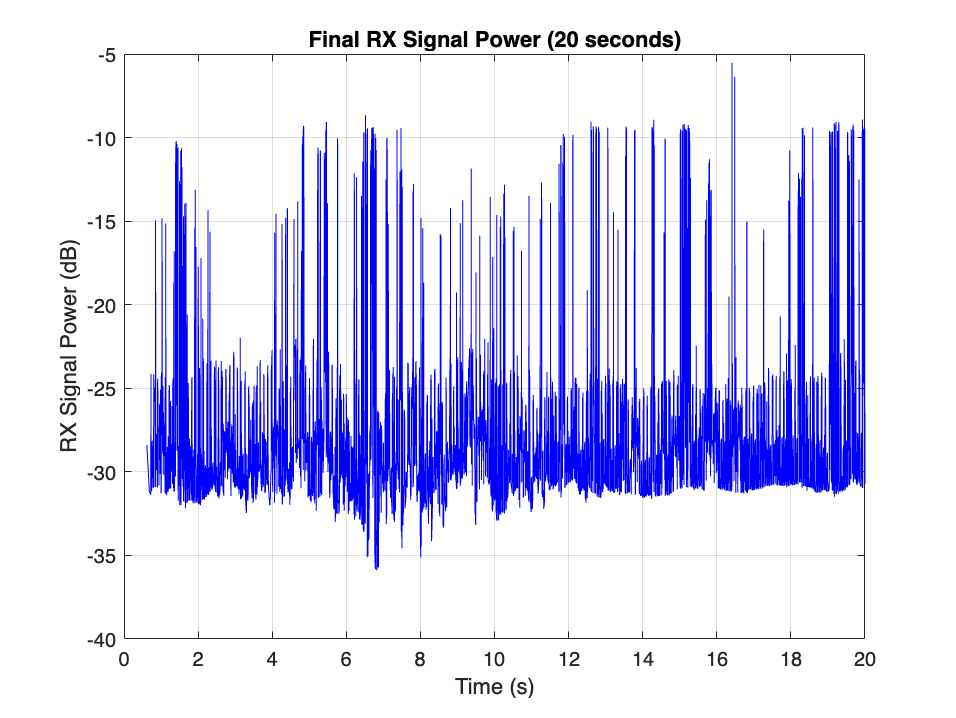





%% Cleanup
release(txPluto);
release(rxPluto);

%% Final visualization
figure;
plot(timeVec, rxPower, '-b');
xlabel('Time (s)'); ylabel('RX Signal Power (dB)');
title('Final RX Signal Power (20 seconds)');
grid on;


fprintf('Demo complete. TX stopped.');

Demo complete. TX stopped.